clear; clc; close all;

%% 1. KONSTANTEN & PARAMETER
% AEB Parameter
v_min = 20 / 3.6;        % System aktiv ab 20 km/h
v_max = 60 / 3.6;        % System aktiv bis 60 km/h
bremskraft_min = 5.0;    % Vollbremsung mit 5 m/s²
ttc_warnung = 2.0;       % FCW Warnung bei 2.0s
ttc_bremse = 1.2;        % AEB Eingriff bei 1.2s

% Fahrer-Übersteuerung (Override) Schwellwerte
SCHWELLE_LENKUNG = 15;   % Grad (Absolutwert)
SCHWELLE_GAS = 10;       % Gaspedalstellung in %

% Simulations-Parameter
time_step = 0.01;
gesamtzeit = 15;
zeit = 0:time_step:gesamtzeit;

% Fußgänger (Pedestrian)
v_pedestrian = 5 / 3.6;  % 5 km/h
pedestrian_x = 35;       % 35m vor dem Auto
pedestrian_y = -3;       % Startet 3m rechts/links der Fahrbahn

% Auto Initialisierung
auto_x = 0;
auto_y = 0;
v_ego = 50 / 3.6;        % 50 km/h Startgeschwindigkeit

%% 2. DATEN-ARRAYS INITIALISIEREN
auto_position_x = zeros(size(zeit));
auto_position_y = zeros(size(zeit));
auto_geschwindigkeit = zeros(size(zeit));

pedestrian_position_x = zeros(size(zeit));
pedestrian_position_y = zeros(size(zeit));

ttc_werte = zeros(size(zeit));
warnung_aktiv = false(size(zeit));
bremse_aktiv = false(size(zeit));
bremskraft = zeros(size(zeit));
driver_override_aktiv = false(size(zeit)); % Zum Speichern, wann Fahrer eingreift

% --- FAHREREINGABEN (Simulation) ---
% Hier simulieren wir Lenkung und Gas. 
% Standardmäßig sind diese 0 (Fahrer macht nichts).
lenkrad_winkel = zeros(size(zeit)); 
gaspedal_pos = zeros(size(zeit));

% >>> TEST-SZENARIO (Optional: Hier Kommentar entfernen um Override zu testen) <<<
% Beispiel: Fahrer lenkt bei Sekunde 1.5 stark ein -> AEB sollte abbrechen
 lenkrad_winkel(zeit > 1.5 & zeit < 3.0) = 20; 

%% 3. INITIALISIERUNG STARTWERTE
auto_position_x(1) = auto_x;
auto_position_y(1) = auto_y;
auto_geschwindigkeit(1) = v_ego;

pedestrian_position_x(1) = pedestrian_x;
pedestrian_position_y(1) = pedestrian_y;

ttc_werte(1) = Inf;

%% 4. HAUPTSIMULATIONSSCHLEIFE
for i = 2:length(zeit)
    
    % --- A. PHYSIK & BEWEGUNG ---
    v_aktuell = auto_geschwindigkeit(i-1);
    
    % Auto Bewegung
    auto_position_x(i) = auto_position_x(i-1) + (v_aktuell * time_step);
    auto_position_y(i) = 0; 
    
    % Fußgänger Bewegung (nur Y-Richtung)
    pedestrian_position_x(i) = pedestrian_x; 
    pedestrian_position_y(i) = pedestrian_position_y(i-1) + (v_pedestrian * time_step);
    
    
    % --- B. SENSORIK & LOGIK ---
    
    % 1. TTC Berechnung
    ttc_werte(i) = berechne_ttc(auto_position_x(i), v_aktuell, pedestrian_position_x(i), pedestrian_position_y(i));
    
    % 2. Systemverfügbarkeit prüfen (Geschwindigkeit)
    system_aktiv = pruefe_geschwindigkeitsbereich(v_aktuell, v_min, v_max);
    
    % 3. Fahrer-Übersteuerung prüfen (NEU!)
    % Wenn Lenkung > Schwelle ODER Gas > Schwelle -> Override = true
    is_steering = abs(lenkrad_winkel(i)) > SCHWELLE_LENKUNG;
    is_gas = gaspedal_pos(i) > SCHWELLE_GAS;
    
    driver_override = is_steering || is_gas;
    driver_override_aktiv(i) = driver_override; % Speichern für Plot
    
    % Wenn System inaktiv (zu langsam/schnell), Werte vom Vor-Schritt übernehmen & Loop fortsetzen
    if ~system_aktiv
      warnung_aktiv(i) = warnung_aktiv(i-1);
      bremse_aktiv(i) = bremse_aktiv(i-1);
      bremskraft(i) = bremskraft(i-1);
      auto_geschwindigkeit(i) = v_aktuell;
      continue;
    end

    % 4. Kollisionswarnung (FCW)
    % Warnung bleibt auch bei Override aktiv (Fahrer soll ja gewarnt werden),
    % nur die Bremsung wird unterdrückt.
    warnung_alt_input = warnung_aktiv(i-1);
    warnung_aktiv(i) = kollisionswarnung(warnung_alt_input, ttc_werte(i), ttc_warnung);
    
    % Optional: Konsolenausgabe für Warnung
    if warnung_aktiv(i) && ~warnung_alt_input
        fprintf('Zeit %.2fs: FCW WARNUNG (Optisch + Akustisch)\n', zeit(i));
    end
    
    % 5. Notbremsung (AEB)
    % Hier übergeben wir jetzt "driver_override" an die Funktion!
    bremse_alt_input = bremse_aktiv(i-1);
    kraft_alt_input  = bremskraft(i-1);
    
    [bremse_aktiv(i), bremskraft(i)] = notbremsung(bremse_alt_input, kraft_alt_input, ...
                                                   ttc_werte(i), ttc_bremse, ...
                                                   bremskraft_min, driver_override);
    
    % --- C. FAHRZEUGREAKTION ---
    
    % Geschwindigkeit update
    if bremse_aktiv(i)
        neue_v = v_aktuell - (bremskraft(i) * time_step);
    else
        neue_v = v_aktuell;
    end
    
    if neue_v < 0; neue_v = 0; end % Kein Rückwärtsfahren
    auto_geschwindigkeit(i) = neue_v;
end

Zeit 0.73s: FCW WARNUNG (Optisch + Akustisch)


ACHTUNG: Notbremsung eingeleitet (TTC=1.20s)
INFO: Notbremsung durch Fahrer abgebrochen!



%% 5. HILFSFUNKTIONEN

function [system_aktiv] = pruefe_geschwindigkeitsbereich(v, v_min, v_max)
    system_aktiv = (v >= v_min && v <= v_max);
end

function [ttc] = berechne_ttc(auto_x, auto_v, ped_x, ped_y)
    dx = ped_x - auto_x;
    dy = abs(ped_y); 
    
    % Kollisionsgefahr nur wenn Fußgänger relevant (dy < 2m) und Auto vor dem Fußgänger
    if dy < 2.0 && dx > 0
        if auto_v > 0
            ttc = dx / auto_v;
        else
            ttc = Inf;
        end
    else
        ttc = Inf;
    end
end

function [warnung_neu] = kollisionswarnung(warnung_alt, ttc, ttc_warnung)
    % Hysterese Logik für Warnung
    if ttc <= ttc_warnung && ~warnung_alt
        warnung_neu = true;
    elseif ttc > ttc_warnung + 0.5
        warnung_neu = false;
    else
        warnung_neu = warnung_alt;
    end
end

% --- UPDATED NOTBREMSUNG MIT OVERRIDE ---
function [bremse_neu, bremskraft_neu] = notbremsung(bremse_alt, bremskraft_alt, ttc, ttc_bremse, bremskraft_min, override)
    
    % Wenn der Fahrer eingreift, wird Bremsung SOFORT deaktiviert/verhindert
    if override
        if bremse_alt
            fprintf('INFO: Notbremsung durch Fahrer abgebrochen!\n');
        end
        bremse_neu = false;
        bremskraft_neu = 0;
        return; % Funktion hier beenden
    end

    % Normale AEB Logik
    if ttc <= ttc_bremse && ~bremse_alt
        bremse_neu = true;
        bremskraft_neu = bremskraft_min;
        fprintf('ACHTUNG: Notbremsung eingeleitet (TTC=%.2fs)\n', ttc);
    elseif bremse_alt && ttc > ttc_bremse + 0.5
        bremse_neu = false;
        bremskraft_neu = 0; 
    else
        bremse_neu = bremse_alt;
        bremskraft_neu = bremskraft_alt;
    end
end

%% 6. VISUALISIERUNG
fprintf('\nSimulation abgeschlossen. Erstelle Plots...\n');


Simulation abgeschlossen. Erstelle Plots...


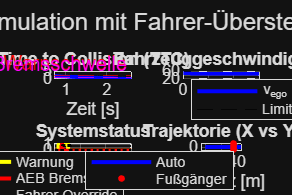


figure('Name', 'AEB Simulation Results', 'Position', [100 100 1200 800]);
sgtitle('AEB Simulation mit Fahrer-Übersteuerung');

% Plot 1: TTC
subplot(2,2,1);
plot(zeit, ttc_werte, 'b', 'LineWidth', 2); hold on;
yline(ttc_warnung, 'r--', 'Warnschwelle');
yline(ttc_bremse, 'm--', 'Bremsschwelle');
ylim([0 5]); grid on;
title('Time to Collision (TTC)');
xlabel('Zeit [s]'); ylabel('TTC [s]');

% Plot 2: Geschwindigkeiten
subplot(2,2,2);
plot(zeit, auto_geschwindigkeit*3.6, 'b', 'LineWidth', 2); hold on;
yline(v_min*3.6, 'k--'); yline(v_max*3.6, 'k--');
grid on;
title('Fahrzeuggeschwindigkeit');
xlabel('Zeit [s]'); ylabel('v [km/h]');
legend('v_{ego}', 'Limits', 'Location', 'SouthWest');

% Plot 3: Status Flags (Warnung, Bremse, Override)
subplot(2,2,3);
% Wir versetzen die Linien leicht vertikal, damit man sie besser sieht
plot(zeit, warnung_aktiv, 'y', 'LineWidth', 2); hold on;
plot(zeit, bremse_aktiv * 0.9, 'r', 'LineWidth', 2);
plot(zeit, driver_override_aktiv * 0.8, 'k:', 'LineWidth', 1.5);
ylim([-0.1 1.2]); grid on;
title('Systemstatus');
legend('Warnung', 'AEB Bremsung', 'Fahrer Override');
xlabel('Zeit [s]'); ylabel('Logisch (1=True)');

% Plot 4: Trajektorie (Vogelperspektive)
subplot(2,2,4);
plot(auto_position_x, auto_position_y, 'b', 'LineWidth', 2); hold on;
plot(pedestrian_position_x, pedestrian_position_y, 'r.', 'MarkerSize', 10);
% Kollisionsbox zeichnen
rectangle('Position', [pedestrian_x-2, -2, 4, 4], 'EdgeColor', 'r', 'LineStyle', '--');
grid on; axis equal;
title('Trajektorie (X vs Y)');
xlabel('Distanz [m]'); ylabel('Querversatz [m]');
ylim([-5 5]); xlim([-5 45]);
legend('Auto', 'Fußgänger', 'Gefahrenzone');